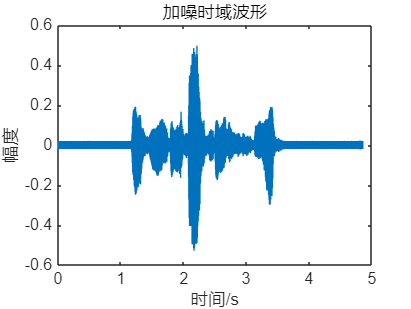

clc;clear;
[y0,Fs]=audioread('dspx1.wav');
t = (0:length(y0)-1) / Fs;
f=4000;
A=0.02;
Nt=(A*cos(2*pi*f*t))';
y=y0+Nt;

%添加噪声后
% 绘制时域波形
figure;
plot(t, y);
title('加噪时域波形');
xlabel('时间/s');
ylabel('幅度');

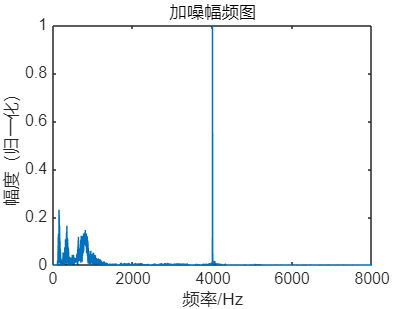

% 绘制幅频图
figure;
n = length(y); 
Y0 = fft(y); 
f = (0:n-1)*Fs/n;
Y = abs(Y0)/abs(max(Y0)); 
plot(f, Y);
title('加噪幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);

%利用巴特沃兹低通滤波器
%巴特沃兹滤波器,通带截至频率为2000Hz，阻带截至频率为3800Hz
wp=2000*2*pi/Fs;
ws=3800/Fs*2*pi;
rp=3;
rs=90;
wp=2*Fs*tan (wp/2) ;
ws=2*Fs*tan(ws/2) ;
[N, wn]=buttord(wp,ws, rp, rs, 's');
[A,B]=butter (N, wn, 's') ;
[num1, den1]=bilinear(A, B,Fs);

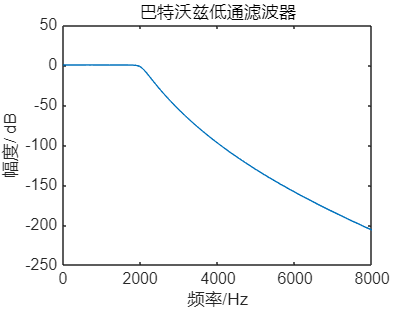

[h1,w]=freqz(num1, den1) ;
w=w/2/pi*Fs;
figure;
plot(w,20*log10(abs(h1)));
xlim([0,8000]);
xlabel('频率/Hz') ; 
ylabel('幅度/ dB') ;
title('巴特沃兹低通滤波器');

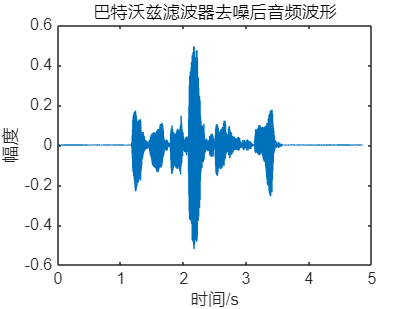

%巴特沃兹滤波器去噪
y1=filter(num1,den1,y);
figure;
plot(t,y1);
title('巴特沃兹滤波器去噪后音频波形');
xlabel('时间/s');
ylabel('幅度');

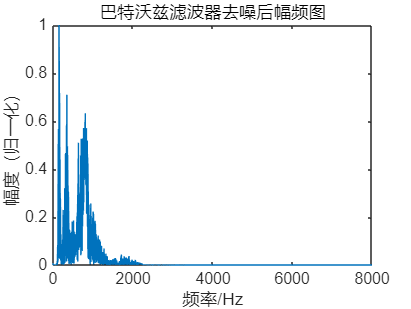

figure;
Y1 = fft(y1); 
M1=max(Y1);
f = (0:n-1)*Fs/n;
Y1 = abs(Y1)/abs(M1); 
plot(f, Y1);
title('巴特沃兹滤波器去噪后幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);

%利用椭圆低通滤波器
%椭圆低通波器,通带截至频率为2000Hz，阻带截至频率为3800Hz
wp=2000*2*pi/Fs;
ws=3800/Fs*2*pi;
rp=3;
rs=90;
wp=2*Fs*tan (wp/2) ;
ws=2*Fs*tan(ws/2) ;
[N, wn]=ellipord(wp,ws, rp, rs, 's');
[A,B]=ellip(N,rp,rs,wp,'s') ;
[num2, den2]=bilinear(A, B,Fs);

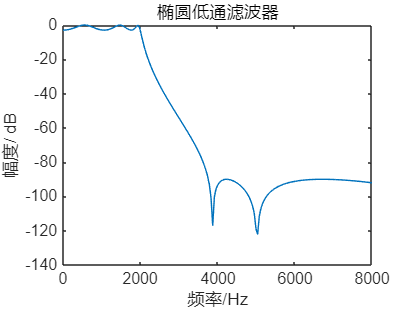

[h2,w]=freqz(num2, den2) ;
w=w/2/pi*Fs;
figure;
plot(w,20*log10(abs(h2)));
xlim([0,8000]);
xlabel('频率/Hz') ; 
ylabel('幅度/ dB') ;
title('椭圆低通滤波器');

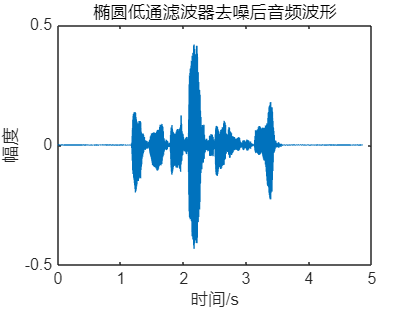

%椭圆低通滤波器滤波
y2=filter(num2,den2,y);
figure;
plot(t,y2);
title('椭圆低通滤波器去噪后音频波形');
xlabel('时间/s');
ylabel('幅度');

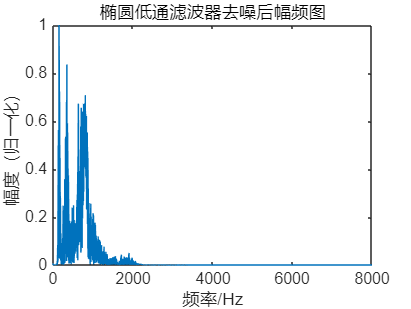

figure;
Y2 = fft(y2); 
M1=max(Y2);
f = (0:n-1)*Fs/n;
Y2 = abs(Y2)/abs(M1); 
plot(f, Y2);
title('椭圆低通滤波器去噪后幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);